# t_motionCorrection

Illustrates how to compensate for head movement (within a scanning session and between scans) using sample data set [erniePRF](erniePRF)

Dependencies: Remote Data Toolbox Freesurfer Paths

% This tutorial is part of a sequence. Run 
%   t_initAnatomyFromFreesurfer
%   t_meshesFromFreesurfer *optional
%   t_initVistaSession
%   t_alignInplaneToVolume *optional
%   t_installSegmentation  *optional
%   t_sliceTiming
% prior to running this tutorial. 
%
% Summary
% - Motion correction: Run within- and between-scan motion compensation
%                       using Nestares algorithm
%
% - Visualization:     View motion estimates, view a slice before and after,
%                       view a movie of one scan before and after
%
% Tested 09/14/2016 - MATLAB R2015a, Mac OS 10.11.6 (Silvia's computer)  
%
%  See also: t_initAnatomyFromFreesurfer t_meshesFromFreesurfer
%  t_initVistaSession t_alignInplaneToVolume t_installSegmentation
%  t_sliceTiming
%
%  Winawer lab (NYU)

## Organize functional data

% Find ernie PRF session in scratch directory
erniePathTemp      = fullfile(vistaRootPath, 'local', 'scratch', 'erniePRF');

if ~exist(erniePathTemp, 'dir')
    help(mfilename)
    error('Please run  pre-requisite tutorials')
end

% Navigate
cd(erniePathTemp);

## Motion correction

% Open a hidden view (a session without graphical user interface)
vw = initHiddenInplane();

Initializing HIDDEN Inplane view
[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [80.000,104.000,12.000] pix.


[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
Saving Parameter Map: /Users/jonathanwinawer/matlab/toolboxes/vistasoft/local/scratch/erniePRF/Inplane/Timed/meanMap.mat
Initializing HIDDEN Inplane view
[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [80.000,104.000,12.000] pix.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
Updated dataTYPES variable in mrSESSION.mat.
Created directory /Users/jonathanwinawer/matlab/toolboxes/vistasoft/local/scratch/erniePRF/Inplane/BwScansMotionComp/TSeries
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. R

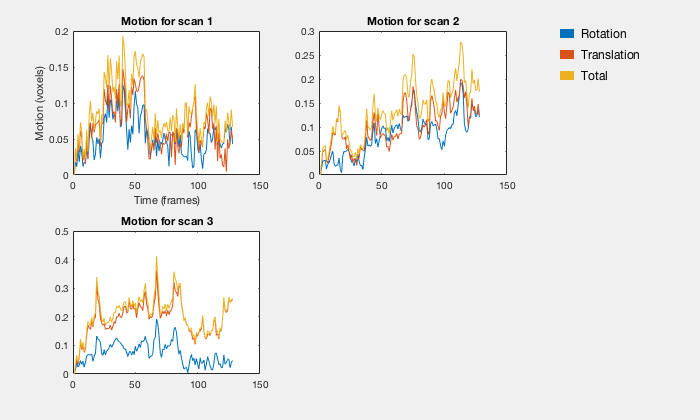


% We will use the slice-time corrected dataTYPE called 'Timed' obtained
% from t_sliceTiming, not the original data, for motion compensation
vw = viewSet(vw, 'Current DataTYPE', 'Timed');
    
% Apply the motion correction
if  any(strcmpi({dataTYPES.name}, 'MotionComp')),
    % Do not apply motion compensation if it was already done
    warning('Motion compensation has already been done on this data set. Skipping.')
    % Visualize motion estimates from saved data
    if exist('Within_Scan_Motion_Est.fig', 'file'),
        openfig('Within_Scan_Motion_Est.fig', 'visible');
    end
else
    % Do it. This is slow. It might take 5 minutes.
    tic, vw = motionCompNestaresFull(vw); toc
end

## Visualization

% First, let's look at a single slice at a single time point from the
% original and from the motion corrected dataTYPES
whichSlice = round(viewGet(vw, 'num slices')/2); 

vw = viewSet(vw, 'Current DataTYPE', 'Original');
vw = viewSet(vw, 'Current Scan', 3);
[~, nii]  = loadtSeries(vw, 1);

[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [52.000,40.000,12.000] pix.


tSeries.orig = niftiGet(nii, 'data');

vw = viewSet(vw, 'Current DataTYPE', 'MotionComp');
vw = viewSet(vw, 'Current Scan', 3);
[~, nii]  = loadtSeries(vw, 1);

[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.


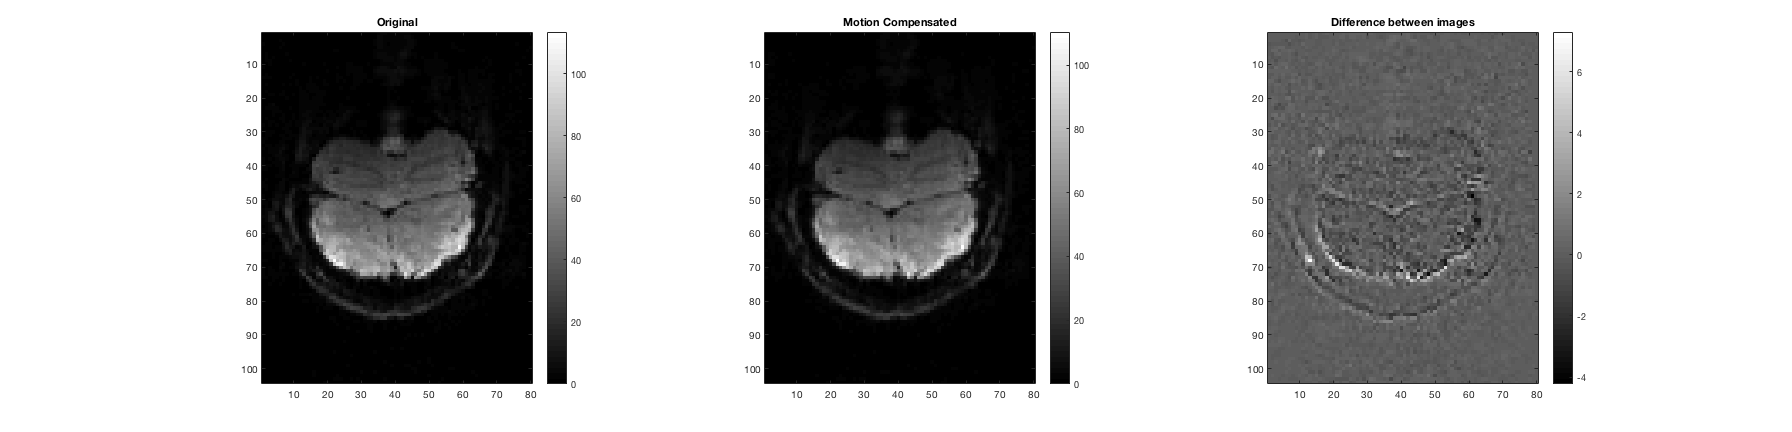

tSeries.motion = niftiGet(nii, 'data');

fH = mrvNewGraphWin('One Slice Before and After Motion Compensation', 'wide'); 



subplot(1,3,1)
imagesc(tSeries.orig(:,:,whichSlice,end)); 
axis image, colormap gray, title('Original'); colorbar

subplot(1,3,2)
imagesc(tSeries.motion(:,:,whichSlice,end)); 
axis image, title('Motion Compensated'); colorbar


subplot(1,3,3)
imagesc(tSeries.motion(:,:,whichSlice,end) - tSeries.orig(:,:,whichSlice,end)); 
axis image,  title('Difference between images'); colorbar

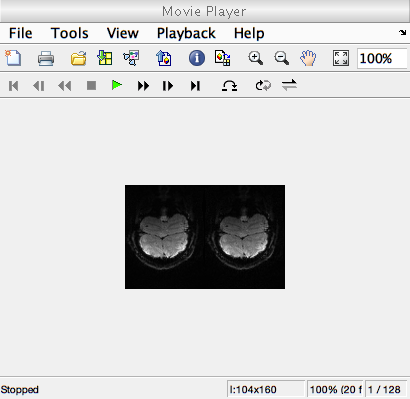


% The motion compensated image and the original image are very similar, but
% they differ in subtle ways. The motion compensated image is slightly
% blurrier due to the resampling involved in motion compensation. The
% regions in the images with the biggest differences are around the edges
% of the brain tissue, as evident in the third plot. 

% Second, view movies of the data
movieBefore = squeeze(tSeries.orig(:,:,whichSlice,:));
movieAfter  = squeeze(tSeries.motion(:,:,whichSlice,:));
movieBoth   = cat(2, movieBefore, movieAfter);
movieBoth = movieBoth - min(movieBoth(:));
movieBoth = movieBoth / max(movieBoth(:));
implay(movieBoth)

mH = get(gcf, 'number');
% For better visibility, you might zoom in on the movie using the zoom
% button on the menu bar, and then set the movie to loop.
% This subject did not move much. Hence there is not too much difference
% between the movies. But if you look carefully, you can see slightly more
% motion on the left (the original time series) than the right (the motion
% compensated time series).

## Clean up

close(viewGet(vw, 'figure number')); 

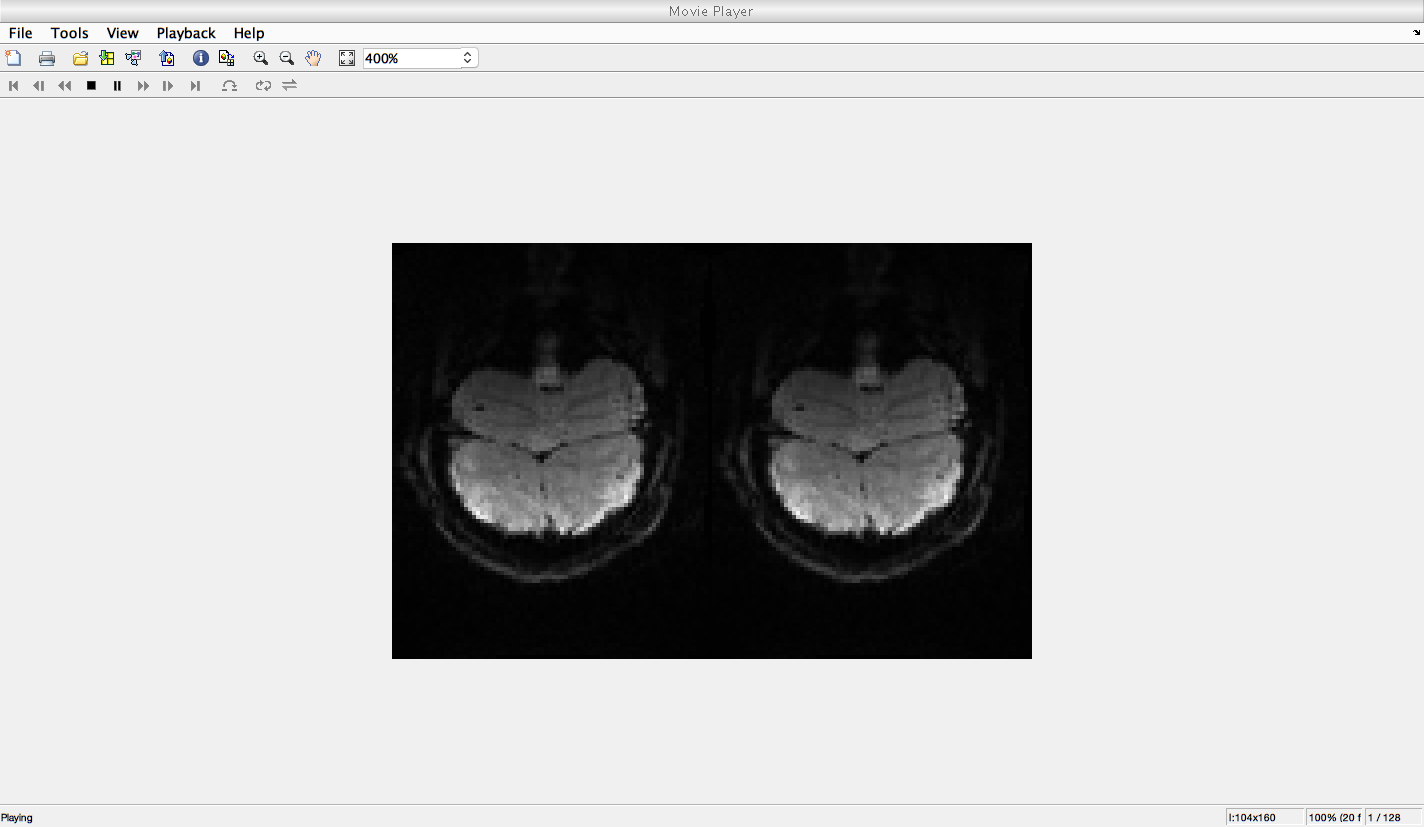

close(fH); % close plot
mrvCleanWorkspace;